## FA3 strain

modelName = 'FA3NFB';
open_system(modelName)
set_param(modelName + "/Manual Switch1",'sw','1')

set_param(modelName + "/Manual Switch2",'sw','1')
set_param(modelName + "/Model selection (manual)",'Value','1') % FA3 model

set_param(modelName + "/Manual Switch3",'sw','0')
set_param(modelName + "/To test manually",'Value','107.7158') % optimum for FA3

ここから

spv_length = 100;
k_E_nom = 0.64273576903494289;
setPointValues = linspace(0,5,spv_length)*k_E_nom; % k_E

for i = 1:1:spv_length
    in(i) = Simulink.SimulationInput(modelName);
    in(i) = in(i).setVariable('k_E',setPointValues(i),'Workspace',modelName);
end

out_FA3 = sim(in,'ShowSimulationManager','on','ShowProgress','on')

[09-Nov-2023 23:31:20] シミュレーションの実行中...
[09-Nov-2023 23:31:21] シミュレーション実行 1/100 が完了
[09-Nov-2023 23:31:22] シミュレーション実行 2/100 が完了
[09-Nov-2023 23:31:23] シミュレーション実行 3/100 が完了
[09-Nov-2023 23:31:23] シミュレーション実行 4/100 が完了
[09-Nov-2023 23:31:24] シミュレーション実行 5/100 が完了
[09-Nov-2023 23:31:24] シミュレーション実行 6/100 が完了
[09-Nov-2023 23:31:25] シミュレーション実行 7/100 が完了
[09-Nov-2023 23:31:25] シミュレーション実行 8/100 が完了
[09-Nov-2023 23:31:26] シミュレーション実行 9/100 が完了
[09-Nov-2023 23:31:27] シミュレーション実行 10/100 が完了
[09-Nov-2023 23:31:27] シミュレーション実行 11/100 が完了
[09-Nov-2023 23:31:28] シミュレーション実行 12/100 が完了
[09-Nov-2023 23:31:28] シミュレーション実行 13/100 が完了
[09-Nov-2023 23:31:29] シミュレーション実行 14/100 が完了
[09-Nov-2023 23:31:29] シミュレーション実行 15/100 が完了
[09-Nov-2023 23:31:30] シミュレーション実行 16/100 が完了
[09-Nov-2023 23:31:31] シミュレーション実行 17/100 が完了
[09-Nov-2023 23:31:31] シミュレーション実行 18/100 が完了
[09-Nov-2023 23:31:32] シミュレーション実行 19/100 が完了
[09-Nov-2023 23:31:32] シミュレーション実行 20/100 が完了
[09-Nov-2023 23:31:33] シミュレーション実行 21/100 が完了
[09-Nov-2023 23:31:33] シミ

out_FA3 = 1x100 Simulink.SimulationOutput 配列



FFAfinal = zeros(spv_length,2);
FFAfinal(:,1) = setPointValues;
for i = 1:1:spv_length
    FFAfinal(i,2) = out_FA3(i).logsout{1}.Values.Data(end);
end

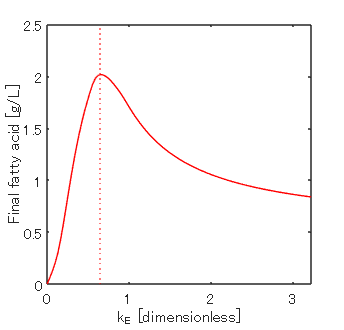

figure('Position', [120 120 250 240]);
plot(FFAfinal(:,1),FFAfinal(:,2),'r-')
xline(k_E_nom,'r:')
xlim([0 k_E_nom*5])
ylim([0 2.5])
xlabel('k_E [dimensionless]')
% xticks([1 10 40 100 400 1000])
% yticks([0 20 40 60 80])
ylabel('Final fatty acid [g/L]')
set(gca,'xscale','linear')

save(append('optInput_',modelName),'optInput')
sdo.setValueInModel(modelName,optInput);